 clc;
 close all;
 clear all;
 K=1.38*10^(-23);
 T=293;
 F_dB=5;
 F=10^(F_dB/10)

F = 3.1623

 PSD=K*T*F

PSD = 1.2786e-20

 B=30*(10^3):(10^3):40*(10^3);
 NP=PSD*B;
 NP_dB=10*log10(2*NP)

NP_dB =  -151.1510 -151.0086 -150.8707 -150.7371 -150.6074 -150.4816 -150.3592 -150.2402 -150.1244 -150.0116 -149.9016


 BER=10^(-4);
 x=(1-(2*BER));
 SNR=(x^2/(1-(x^2))*2);
 SNR_dB = 10*log10(SNR)

SNR_dB = 36.9884

Gt=12;
 Gr=5;
 L=167;
 M=10;
 Lc=3;
 Pt=SNR_dB-Gt-Gr+L+M+Lc+NP_dB

Pt =    48.8374   48.9798   49.1177   49.2513   49.3810   49.5068   49.6292   49.7482   49.8640   49.9768   50.0868


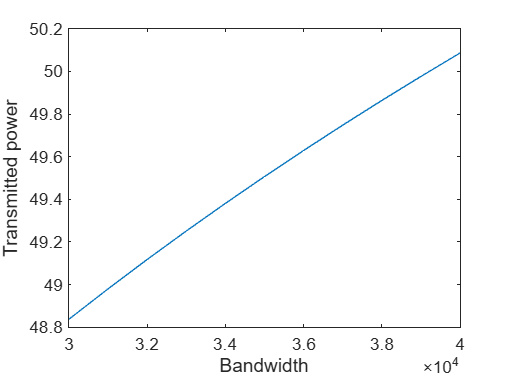

plot(B,Pt);
 xlabel('Bandwidth');
 ylabel('Transmitted power'); 